# Analysis trajectory of multi bodyparts

clear; close all;

## Load TrajGroupClass file

[TrajGroupFileName, TrajGroupFolder] = uigetfile("F:\YuLab\Work\GPS\Video\*.mat");
if ~TrajGroupFileName
    return
end
TrajGroupFilePath = fullfile(TrajGroupFolder, TrajGroupFileName);

load(TrajGroupFilePath);

FigFolder = fullfile(TrajGroupFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

## Calculate distance matrix

Features = [
    ["AngleHead" "PosXHead" "PosYHead"];...
    ["AngSpeedHead" "SpeedXHead" "SpeedYHead"]
    ];
FeatureLabels = [
    ["Head angle (°)" "Head x position (px)" "Head y position (px)"]; ...
    ["Head ang. speed (°/ms)" "Head x speed (px/ms)" "Head y speed (px/ms)"]
    ];

TraceGathered = obj.gatherTrace(Features(:));

MatWarpAlign = obj.trace2mat(TraceGathered, obj.TimeWarped, obj.TimeWarpAlign);
TraceWarpAlign = obj.mat2trace(MatWarpAlign, obj.TimeWarpAlign);

obj.DistMatLw = obj.calDist(TraceWarpAlign);
obj.save(TrajGroupFolder);


MatOutAlign = obj.trace2mat(TraceGathered, obj.TimeFromOut, 0:10:200);
TraceOutAlign = obj.mat2trace(MatOutAlign, 0:10:200);

DistOutMatLw = obj.calDist(TraceOutAlign);



## Extract information

FPs = [.5 1 1.5];
Info = obj.TrialInfo;

opts.trial_ctrl = cell(1, 2);
opts.num_ctrl = zeros(1, 2);
opts.color_ctrl = cell(1, 2);
opts.session_ctrl = cell(1, 2);
opts.session_date_ctrl = cell(1, 2);
opts.session_num_ctrl = cell(1, 2);
opts.session_sep_ctrl = cell(1, 2);

opts.trial_chemo = cell(1, 2);
opts.num_chemo = zeros(1, 2);
opts.color_chemo = cell(1, 2);
opts.session_chemo = cell(1, 2);
opts.session_date_chemo = cell(1, 2);
opts.session_num_chemo = cell(1, 2);
opts.session_sep_chemo = cell(1, 2);

for fp = 1:3
    for p = 1:2

        opts.trial_ctrl{fp, p} = find(Info.Label=="Control" & Info.Stage==1 & Info.PortCorrect==obj.Ports(p) & Info.HD>0.5 & Info.FP==FPs(fp));
        opts.num_ctrl(fp, p) = length(opts.trial_ctrl{fp, p});
        opts.color_ctrl{fp, p} = repmat(GPSColor.Control, opts.num_ctrl(fp, p), 1);
        opts.session_ctrl{fp, p} = Info.Session(opts.trial_ctrl{fp, p});
        opts.session_date_ctrl{fp, p} = unique(opts.session_ctrl{fp, p});
        opts.session_num_ctrl{fp, p} = zeros(length(opts.session_date_ctrl), 1);
        for k = 1:length(opts.session_date_ctrl{fp, p})
            opts.session_num_ctrl{fp, p}(k) = sum(opts.session_ctrl{fp, p}==opts.session_date_ctrl{fp, p}(k));
        end
        opts.session_sep_ctrl{fp, p} = cumsum(opts.session_num_ctrl{fp, p});

        opts.trial_chemo{fp, p} = find(Info.Label=="Chemo" & Info.Stage==1 & Info.PortCorrect==obj.Ports(p) & Info.HD>0.5 & Info.FP==FPs(fp));
        opts.num_chemo(fp, p) = length(opts.trial_chemo{fp, p});
        opts.color_chemo{fp, p} = repmat(GPSColor.Treat, opts.num_chemo(fp, p), 1);
        opts.session_chemo{fp, p} = Info.Session(opts.trial_chemo{fp, p});
        opts.session_date_chemo{fp, p} = unique(opts.session_chemo{fp, p});
        opts.session_num_chemo{fp, p} = zeros(length(opts.session_date_chemo), 1);
        for k = 1:length(opts.session_date_chemo{fp, p})
            opts.session_num_chemo{fp, p}(k) = sum(opts.session_chemo{fp, p}==opts.session_date_chemo{fp, p}(k));
        end
        opts.session_sep_chemo{fp, p} = cumsum(opts.session_num_chemo{fp, p});

    end
end

opts.trial = cellfun(@(x, y) [x; y], opts.trial_ctrl, opts.trial_chemo, 'UniformOutput', false);
opts.num_trial = opts.num_ctrl + opts.num_chemo;

opts.label = cell(3, 2);
for fp = 1:3
    for p = 1:2
        opts.label{fp, p} = [zeros(opts.num_ctrl(fp, p), 1); ones(opts.num_chemo(fp, p), 1)];
    end
end

opts.color_trial = cellfun(@(x, y) [x; y], opts.color_ctrl, opts.color_chemo, 'UniformOutput', false);
opts.session_trial = cellfun(@(x, y) [x; y], opts.session_ctrl, opts.session_chemo, 'UniformOutput', false);
opts.session_date = cellfun(@(x, y) [x; y], opts.session_date_ctrl, opts.session_date_chemo, 'UniformOutput', false);
opts.session_num = cellfun(@(x, y) [x; y], opts.session_num_ctrl, opts.session_num_chemo, 'UniformOutput', false);
opts.session_sep = cellfun(@(x, y) [x; y], opts.session_sep_ctrl, opts.session_sep_chemo, 'UniformOutput', false);

opts.num_size = min(min([opts.num_ctrl opts.num_chemo]));
opts.num_show = min([50 opts.num_size]);


# Plot trace of features 

ax_w = 4; ax_h = 3;
ax_sep_w = 1.5; ax_sep_h = .6;

ax_pos = cell(size(Features));
for i = 1:size(Features, 1)
    for j = 1:size(Features, 2)
        ax_pos{i, j} = [1.5 + (j-1)*(ax_w+ax_sep_w) 1.2 + (size(Features, 1)-i)*(ax_h+ax_sep_h)];
    end
end

## aligned to poke-in

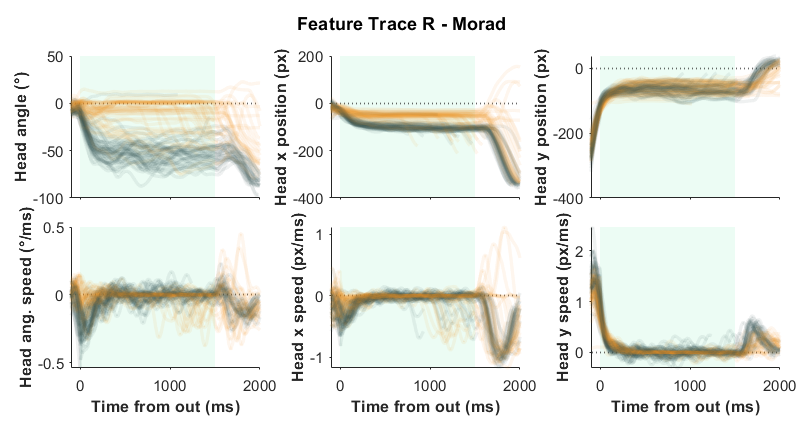

for fp = 1:3
    for p = 1:2
        fig_trace_in = figure(51); clf(51);
        set(fig_trace_in, 'Units', 'Centimeters', 'Position', [5 5 17 9], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on', 'ToolBar', 'none');

        set_fig_title(fig_trace_in, sprintf("Feature Trace %s - %s", obj.Ports(p), obj.ANM));

        for f = 1:length(Features(:))
            ax_back = axes;
            set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

            ax_front = axes;
            set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

            j_trials = [opts.trial_ctrl{fp, p}(randperm(opts.num_ctrl(fp, p), opts.num_show)); opts.trial_chemo{fp, p}(randperm(opts.num_chemo(fp, p), opts.num_show))];
            j_color = [opts.color_ctrl{fp, p}(1:opts.num_show, :); opts.color_chemo{fp, p}(1:opts.num_show, :)];
            j_shuffle = randperm(length(j_trials));

            for i = 1:length(j_trials)
                i_trial = j_trials(j_shuffle(i));
                i_color = j_color(j_shuffle(i), :);
                plot(ax_front, obj.TimeFromIn{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
            end

            ax_front.XLim = [-100 2000];
            ax_front.YLabel.String = FeatureLabels(f);
            ax_front.YLabel.FontWeight = "bold";

            if ~mod(f, 2)
                ax_front.XLabel.String = "Time from out (ms)";
                ax_front.XLabel.FontWeight = "bold";
            else
                ax_front.XTickLabel = [];
            end

            ax_back.XLim = ax_front.XLim;
            ax_back.YLim = ax_front.YLim;
            fill(ax_back, 1000*[0 FPs(fp) FPs(fp) 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
                'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', .1, 'EdgeColor', 'none');
            yline(ax_back, 0, ':', 'LineWidth', 1);

            drawnow;
        end

        save_name = "FeatureTraceIn_" + obj.Ports(p) + "_" + obj.ANM + "_" + obj.Task + "_" + string(1000*FPs(fp)) + ".jpg";
        save_path = fullfile(FigFolder, save_name);
        exportgraphics(fig_trace_in, save_path, 'Resolution', 600);
    end
end

## aligned to poke-out

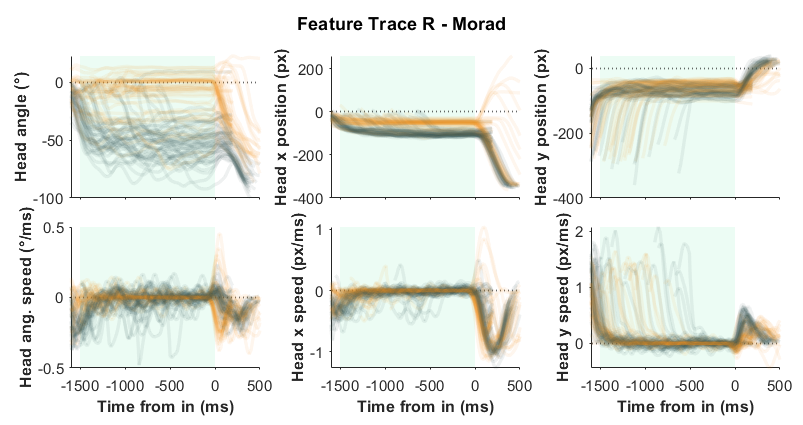

for fp = 1:3
    for p = 1:2
        fig_trace_out = figure(51); clf(51);
        set(fig_trace_out, 'Units', 'Centimeters', 'Position', [5 5 17 9], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on', 'ToolBar', 'none');

        set_fig_title(fig_trace_out, sprintf("Feature Trace %s - %s", obj.Ports(p), obj.ANM));

        w_now = 1.5; h_now = 20;
        for f = 1:length(Features(:))
            ax_back = axes;
            set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

            ax_front = axes;
            set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

            j_trials = [opts.trial_ctrl{fp, p}(randperm(opts.num_ctrl(fp, p), opts.num_show)); opts.trial_chemo{fp, p}(randperm(opts.num_chemo(fp, p), opts.num_show))];
            j_color = [opts.color_ctrl{fp, p}(1:opts.num_show, :); opts.color_chemo{fp, p}(1:opts.num_show, :)];
            j_shuffle = randperm(length(j_trials));

            for i = 1:length(j_trials)
                i_trial = j_trials(j_shuffle(i));
                i_color = j_color(j_shuffle(i), :);
                plot(ax_front, obj.TimeFromOut{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
            end

            ax_front.XLim = [-1600 500];
            ax_front.YLabel.String = FeatureLabels(f);
            ax_front.YLabel.FontWeight = "bold";

            if ~mod(f, 2)
                ax_front.XLabel.String = "Time from out (ms)";
                ax_front.XLabel.FontWeight = "bold";
            else
                ax_front.XTickLabel = [];
            end

            ax_back.XLim = ax_front.XLim;
            ax_back.YLim = ax_front.YLim;
            fill(ax_back, 1000*[0 -FPs(fp) -FPs(fp) 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
                'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', .1, 'EdgeColor', 'none');
            yline(ax_back, 0, ':', 'LineWidth', 1);

            drawnow;
        end

        save_name = "FeatureTraceOut_" + obj.Ports(p) + "_" + obj.ANM + "_" + obj.Task + "_" + string(FPs(fp)) + ".jpg";
        save_path = fullfile(FigFolder, save_name);
        exportgraphics(fig_trace_out, save_path, 'Resolution', 600);
    end
end

## Plot trace of features (warped)

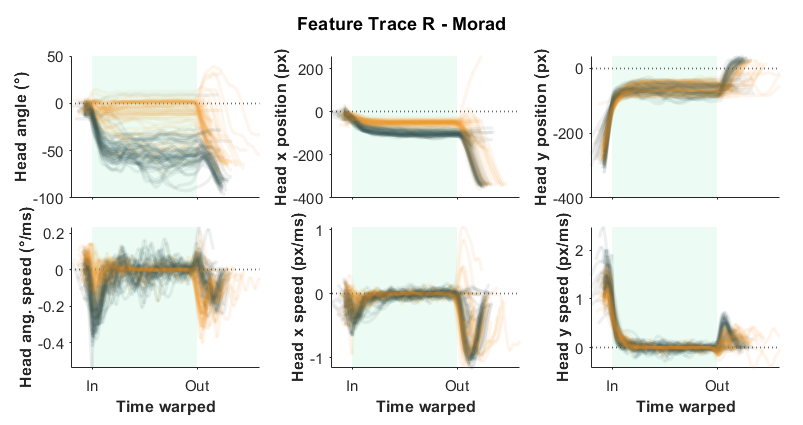

for fp = 1:3
    for p = 1:2
        fig_trace_warp = figure(51); clf(51);
        set(fig_trace_warp, 'Units', 'Centimeters', 'Position', [5 5 17 9], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on', 'ToolBar', 'none');

        set_fig_title(fig_trace_warp, sprintf("Feature Trace %s - %s", obj.Ports(p), obj.ANM));

        w_now = 1.5; h_now = 20;
        for f = 1:length(Features(:))
            ax_back = axes;
            set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

            ax_front = axes;
            set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos{f} ax_w ax_h], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

            j_trials = [opts.trial_ctrl{fp, p}(randperm(opts.num_ctrl(fp, p), opts.num_show)); opts.trial_chemo{fp, p}(randperm(opts.num_chemo(fp, p), opts.num_show))];
            j_color = [opts.color_ctrl{fp, p}(1:opts.num_show, :); opts.color_chemo{fp, p}(1:opts.num_show, :)];
            j_shuffle = randperm(length(j_trials));

            for i = 1:length(j_trials)
                i_trial = j_trials(j_shuffle(i));
                i_color = j_color(j_shuffle(i), :);
                plot(ax_front, obj.TimeWarped{i_trial}, obj.(Features(f)){i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
            end

            ax_front.XLim = [-.2 1.6];
            ax_front.YLabel.String = FeatureLabels(f);
            ax_front.YLabel.FontWeight = "bold";

            ax_front.XTick = [0 1];
            ax_front.XTickLabel = ["In" "Out"];

            if ~mod(f, 2)
                ax_front.XLabel.String = "Time warped";
                ax_front.XLabel.FontWeight = "bold";
            else
                ax_front.XTickLabel = [];
            end

            ax_back.XLim = ax_front.XLim;
            ax_back.YLim = ax_front.YLim;
            fill(ax_back, [0 1 1 0], [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', ...
                'FaceColor', GPSColor.("Port"+obj.Ports(p)), 'FaceAlpha', .1, 'EdgeColor', 'none');
            yline(ax_back, 0, ':', 'LineWidth', 1);

            drawnow;
        end

        save_name = "FeatureTraceWarp_" + obj.Ports(p) + "_" + obj.ANM + "_" + obj.Task + "_" + string(FPs(fp)) + ".jpg";
        save_path = fullfile(FigFolder, save_name);
        exportgraphics(fig_trace_warp, save_path, 'Resolution', 600);
    end
end

## Plot speed of head

ax_size = [10 6];
ax_pos = [1.5 16.5; 1.5 9; 1.5 1.5; 14 16.5; 14 9; 14 1.5];

fig_speed = figure(54); clf(54);
set(fig_speed, 'Units', 'Centimeters', 'Position', [1 1 26 23.7], 'PaperPositionMode', 'Auto', 'Color', 'w');

set_fig_title(fig_speed, sprintf("Head Speed %s - %s", obj.Ports(p), obj.ANM));

for p = 1:2
    for k = 1:3
        switch k
            case 1
                k_time_trace = obj.TimeFromIn;
                k_time_mat = obj.TimeMatIn;
                k_fill = 1000*[0 obj.TaskFP obj.TaskFP 0];
                k_fill_c = 'm';
                k_x_label = 'Time from in (ms)';
            case 2
                k_time_trace = obj.TimeFromOut;
                k_time_mat = obj.TimeMatOut;
                k_fill = -1000*[0 obj.TaskFP obj.TaskFP 0];
                k_fill_c = 'm';
                k_x_label = 'Time from out (ms)';
            case 3
                k_time_trace = obj.TimeWarped;
                k_time_mat = obj.TimeMatWarp;
                k_fill = [0 1 1 0];
                k_fill_c = 'c';
                k_x_label = 'Time warped';
        end
        ax_back = axes;
        set(ax_back, 'Units', 'Centimeters', 'Position', [ax_pos(k+p*3-3, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'XColor', 'none', 'YColor', 'none');

        ax_front = axes;
        set(ax_front, 'Units', 'Centimeters', 'Position', [ax_pos(k+p*3-3, :) ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');

        j_trials = [opts.trial_ctrl{p}(randperm(opts.num_ctrl(p), opts.num_show)); opts.trial_chemo{p}(randperm(opts.num_chemo(p), opts.num_show))];
        j_color = [opts.color_ctrl{p}(1:opts.num_show, :); opts.color_chemo{p}(1:opts.num_show, :)];
        j_shuffle = randperm(length(j_trials));

        for i = 1:length(j_trials)
            i_trial = j_trials(j_shuffle(i));
            i_color = j_color(j_shuffle(i), :);
            plot(ax_front, k_time_trace{i_trial}, obj.SpeedHead{i_trial}, 'Color', [i_color .08], 'LineWidth', 2);
        end

        ax_front.XLim = k_time_mat([1 end]);
        ax_front.YLabel.String = "Head speed (px/ms)";
        ax_front.YLabel.FontWeight = "bold";

        ax_front.XLabel.String = k_x_label;
        ax_front.XLabel.FontWeight = "bold";
        if k == 1
            switch p
                case 1
                    ax_front.Title.String = "Left";
                case 2
                    ax_front.Title.String = "Right";
            end
            ax_front.Title.FontWeight = "bold";
            ax_front.Title.Color = GPSColor.("Port"+obj.Ports(p));
        end

        ax_back.XLim = ax_front.XLim;
        ax_back.YLim = ax_front.YLim;
        fill(ax_back, k_fill, [ax_back.YLim(1) ax_back.YLim(1) ax_back.YLim(2) ax_back.YLim(2)], 'r', 'FaceColor', k_fill_c, 'FaceAlpha', .1, 'EdgeColor', 'none');
%         yline(ax_back, 0, ':', 'LineWidth', 1);
    end
end
save_name = "SpeedTrace_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_speed, save_path);


## PCA for features

MatWarpAlign = obj.trace2mat(TraceGathered, obj.TimeWarped, obj.TimeWarpAlign);
[TraceWarpAlign, TimeTraceWarpAlign] = obj.mat2trace(MatWarpAlign, obj.TimeWarpAlign);
ArrayWarpAlign = obj.trace2array(TraceWarpAlign);
ArrayWarpAlign_n = normalize(ArrayWarpAlign, 1, 'range');

[coeffPCA, ArrayWarpAlignPCA, latentPCA, tsquarePCA, explainedPCA, muPCA] = pca(ArrayWarpAlign_n);
n_dim = find(cumsum(explainedPCA)>95, 1);

TraceWarpAlignPCA = obj.array2trace(ArrayWarpAlignPCA, TimeTraceWarpAlign);
MatWarpAlignPCA = obj.trace2mat(TraceWarpAlignPCA, TimeTraceWarpAlign, obj.TimeWarpAlign);

figure('Visible', 'on'); hold on;
colormap('turbo');

for p = 1:2

MatWarpAlignCtrl_j = squeeze(mean(MatWarpAlignPCA(opts.trial_ctrl{p}, :, :), 1));
MatWarpAlignChemo_j = squeeze(mean(MatWarpAlignPCA(opts.trial_chemo{p}, :, :), 1));

patch([MatWarpAlignCtrl_j(:, 1); nan], [MatWarpAlignCtrl_j(:, 2); nan], [linspace(0, 1, length(obj.TimeWarpAlign)) nan], ...
    'EdgeColor', 'interp', 'LineWidth', 2, 'Marker', 'o', 'MarkerFaceColor', 'flat', 'MarkerSize', 2);
patch([MatWarpAlignChemo_j(:, 1); nan], [MatWarpAlignChemo_j(:, 2); nan], [linspace(0, 1, length(obj.TimeWarpAlign)) nan], ...
    'EdgeColor', 'interp', 'LineWidth', 2, 'Marker', 'o', 'MarkerFaceColor', 'flat', 'MarkerSize', 2);
end
% 
% % view(gca, 0, 30)


## Plot distance matrix

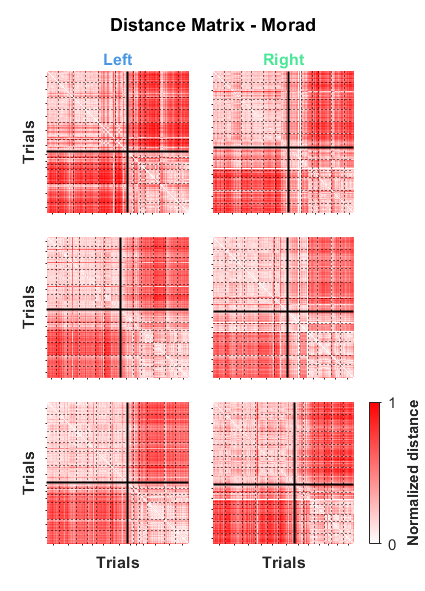

mycolormap = customcolormap([0 1], [1 0 0; 1 1 1]);

fig_dist = figure(55); clf(55);
set(fig_dist, 'Units', 'Centimeters', 'Position', [1 1 9 12.5], 'PaperPositionMode', 'Auto', 'Color', 'w', 'Visible', 'on');

set_fig_title(fig_dist, sprintf("Distance Matrix - %s", obj.ANM));

for fp = 1:3
    for p = 1:2

        ax_dist = axes;
        set(ax_dist, 'Units', 'Centimeters', 'Position', [1+3.5*(p-1) 1+3.5*(3-fp) 3 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');
        colormap(mycolormap);

        j_trials = [opts.trial_ctrl{fp, p}; opts.trial_chemo{fp, p}];
        j_DistM = obj.DistMatLw(opts.trial{fp, p}, opts.trial{fp, p});
        j_DistM = normalize(j_DistM(:), 'range');
        j_DistM = reshape(j_DistM, opts.num_trial(fp, p), opts.num_trial(fp, p));

        imagesc(j_DistM); clim([0 1]);

        j_seps = [opts.session_sep_ctrl{fp, p}; opts.session_sep_ctrl{fp, p}(end)+opts.session_sep_chemo{fp, p}] + 0.5;

        xline(j_seps(1:end-1), 'LineStyle', ':', 'LineWidth', .6, 'Color', 'k', 'Alpha', 1);
        yline(j_seps(1:end-1), 'LineStyle', ':', 'LineWidth', .6, 'Color', 'k', 'Alpha', 1);

        xline(opts.num_ctrl(fp, p)+0.5, 'LineStyle', '-', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);
        yline(opts.num_ctrl(fp, p)+0.5, 'LineStyle', '-', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);

        xlim([.5 length(j_trials)+.5]);
        ylim([.5 length(j_trials)+.5]);

        xticks(j_seps - [opts.session_num_ctrl{fp, p}; opts.session_num_chemo{fp, p}] / 2); xticklabels([]);
        yticks(j_seps - [opts.session_num_ctrl{fp, p}; opts.session_num_chemo{fp, p}] / 2); yticklabels([]);

        if p == 1
            ax_dist.YLabel.String = "Trials";
            ax_dist.YLabel.FontWeight = "Bold";
        end
        if fp==3
            ax_dist.XLabel.String = "Trials";
            ax_dist.XLabel.FontWeight = "Bold";
        end
        if fp==1
            switch p
                case 1
                    title_text = "Left";
                case 2
                    title_text = "Right";
            end
            title(ax_dist, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
        end

    end
end

cb = colorbar(ax_dist, 'Units', 'centimeters', 'Position', [7.8 1 .25 3], 'TickDirection', 'out', 'Ticks', [0 1]);
cb.FontSize = 9;
cb.Label.String = "Normalized distance";
cb.Label.FontSize = 9;
cb.Label.FontWeight = 'bold';


save_name = "DistLwMatrix_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
exportgraphics(fig_dist, save_path, 'Resolution', 600);


## MDS

MDSScore = cell(1, 2);
MDSCost  = cell(1, 2);

fig_mds = figure(56); clf(56);
set(fig_mds, 'Units', 'Centimeters', 'Position', [1 1 20 9.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_mds, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "MDS Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for p = 1:2

    j_DistM = obj.DistMatLw(opts.trial{p}, opts.trial{p});
    j_DistM = normalize(j_DistM(:), 'range');
    j_DistM = reshape(j_DistM, opts.num_trial(p), opts.num_trial(p));

    [MDSScore{p}, MDSCost{p}] = cmdscale(j_DistM);
    
    ax_mds = axes;
    set(ax_mds, 'Units', 'Centimeters', 'Position', [2+8.5*(p-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    j_shuffle = randperm(opts.num_trial(p));
    scatter(ax_mds, MDSScore{p}(j_shuffle,1), MDSScore{p}(j_shuffle,2), 32, opts.color_trial{p}(j_shuffle,:), "filled", 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'none');

    if p == 1
        ax_mds.YLabel.String = "MDS_2";
        ax_mds.YLabel.FontWeight = "Bold";
    end
    ax_mds.XLabel.String = "MDS_1";
    ax_mds.XLabel.FontWeight = "Bold";

    ax_mds.YLim = ax_mds.XLim;

    switch p
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_mds, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
end

% save_name = "MDS_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_mds, save_path);


## t-SNE

tSNEScore = cell(1, 2);

fig_tsne = figure(57); clf(57);
set(fig_tsne, 'Units', 'Centimeters', 'Position', [1 1 20 9.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_tsne, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "t-SNE Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for p = 1:2

    j_DistM = obj.DistMatLw(opts.trial{p}, opts.trial{p});
    j_DistM = normalize(j_DistM(:), 'range');
    j_DistM = reshape(j_DistM, opts.num_trial(p), opts.num_trial(p));

    tSNEScore{p} = tsne_d(j_DistM);
    
    ax_tsne = axes;
    set(ax_tsne, 'Units', 'Centimeters', 'Position', [2+8.5*(p-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    j_shuffle = randperm(opts.num_trial(p));
    scatter(ax_tsne, tSNEScore{p}(j_shuffle,1), tSNEScore{p}(j_shuffle,2), 32, opts.color_trial{p}(j_shuffle,:), "filled", 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'none');

    if p == 1
        ax_tsne.YLabel.String = "t-SNE_2";
        ax_tsne.YLabel.FontWeight = "Bold";
    end
    ax_tsne.XLabel.String = "t-SNE_1";
    ax_tsne.XLabel.FontWeight = "Bold";

    switch p
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_tsne, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
end

save_name = "tSNE_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_tsne, save_path);


# Predict hold phase using movement features

## Entire holding period ([0 1])

### loss function

r_square = @(y, y_fit, ~) 1 - sum((y-y_fit).^2)/sum((y-mean(y)).^2);
var_explained = @(y, y_fit, ~) 1 - var(y-y_fit)/var(y);


### preprocess data

time_bins = 0:0.05:1;
TraceHold = cellfun(@(trace, t) trace(t>=0 & t<=1, :), TraceGathered, obj.TimeWarped, 'UniformOutput', false);
PhaseHold = cellfun(@(t) t(t>=0 & t<=1), obj.TimeWarped, 'UniformOutput', false);

ArrayHoldCtrl = cell(1, 2);
ArrayHoldChemo = cell(1, 2);
ArrayHoldCtrl_n = cell(1, 2);
ArrayHoldChemo_n = cell(1, 2);

PhaseHoldCtrl = cell(1, 2);
PhaseHoldChemo = cell(1, 2);

for p = 1:2
    j_shuffle_ctrl = randperm(opts.num_ctrl(p), opts.num_size);
    j_shuffle_chemo = randperm(opts.num_chemo(p), opts.num_size);

    ArrayHoldCtrl{p} = cell2mat(TraceHold(opts.trial_ctrl{p}(j_shuffle_ctrl))');
    ArrayHoldChemo{p} = cell2mat(TraceHold(opts.trial_chemo{p}(j_shuffle_chemo))');

    ArrayHoldCtrl_n{p} = normalize(ArrayHoldCtrl{p}, 1, "range");
    ArrayHoldChemo_n{p} = normalize(ArrayHoldChemo{p}, 1, "range");

    PhaseHoldCtrl{p} = cell2mat(PhaseHold(opts.trial_ctrl{p}(j_shuffle_ctrl))');
    PhaseHoldChemo{p} = cell2mat(PhaseHold(opts.trial_chemo{p}(j_shuffle_chemo))');
end


### Linear model


MdlHoldCtrl_linear = cell(1, 2);
MdlHoldChemo_linear = cell(1, 2);

fig_linear = figure(58); clf(58);
set(fig_linear, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_linear, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
    'string', "Linear model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);

for p = 1:2
    MdlHoldCtrl_linear{p} = fitrlinear(ArrayHoldCtrl_n{p}, PhaseHoldCtrl{p}, 'KFold', 10);
    MdlHoldChemo_linear{p} = fitrlinear(ArrayHoldChemo_n{p}, PhaseHoldChemo{p}, 'KFold', 10);

    ax_ctrl = axes;
    set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_ctrl = kfoldPredict(MdlHoldCtrl_linear{p});
    %     scatter(MdlHoldCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
    y_fit_ctrl_prob = histcounts2(MdlHoldCtrl_linear{p}.Y, y_fit_ctrl, time_bins, time_bins);
    y_fit_ctrl_prob = y_fit_ctrl_prob';
    y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);

    imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);

    ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_ctrl.YLim = ax_ctrl.XLim;
    ax_ctrl.XTick = 0:5:20;
    ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
    ax_ctrl.YTick = ax_ctrl.XTick;
    ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;

    switch p
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');

    ax_chemo = axes;
    set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_chemo = kfoldPredict(MdlHoldChemo_linear{p});
    y_fit_chemo_prob = histcounts2(MdlHoldChemo_linear{p}.Y, y_fit_chemo, time_bins, time_bins);
    y_fit_chemo_prob = y_fit_chemo_prob';
    y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);

    imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);

    ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_chemo.YLim = ax_chemo.XLim;
    ax_chemo.XTick = 0:5:20;
    ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
    ax_chemo.YTick = ax_chemo.XTick;
    ax_chemo.YTickLabel = ax_chemo.XTickLabel;

    ax_chemo.XLabel.String = "Hold phase";
    ax_chemo.XLabel.FontWeight = "bold";

    if p == 2
        cb.Label.String = "Predict probability";
        cb.Label.FontSize = 11;
        cb.Label.FontWeight = "bold";
    end

    if p == 1
        ax_ctrl.YLabel.String = "Predicted phase Ctrl";
        ax_ctrl.YLabel.FontWeight = "bold";
        ax_ctrl.YLabel.Color = GPSColor.Control;
        ax_chemo.YLabel.String = "Predicted phase Chemo";
        ax_chemo.YLabel.FontWeight = "bold";
        ax_chemo.YLabel.Color = GPSColor.Treat;
    end
end

save_name = "MdlHold_linear_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_linear, save_path);


### Neural network model

% MdlHoldCtrl_nn = cell(1, 2);
% MdlHoldChemo_nn = cell(1, 2);
% 
% fig_nn = figure(60); clf(60);
% set(fig_nn, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% uicontrol('Style', 'text', 'parent', fig_nn, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
%     'string', "Neural network model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% 
% mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
% 
% for p = 1:2
%     MdlHoldCtrl_nn{p} = fitrnet(ArrayHoldCtrl_n{p}, PhaseHoldCtrl{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
%     MdlHoldChemo_nn{p} = fitrnet(ArrayHoldChemo_n{p}, PhaseHoldChemo{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
% 
%     ax_ctrl = axes;
%     set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_ctrl = kfoldPredict(MdlHoldCtrl_nn{p});
%     %     scatter(MdlHoldCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
%     y_fit_ctrl_prob = histcounts2(MdlHoldCtrl_nn{p}.Y, y_fit_ctrl, time_bins, time_bins);
%     y_fit_ctrl_prob = y_fit_ctrl_prob';
%     y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);
% 
%     imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);
% 
%     ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_ctrl.YLim = ax_ctrl.XLim;
%     ax_ctrl.XTick = 0:5:20;
%     ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
%     ax_ctrl.YTick = ax_ctrl.XTick;
%     ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;
% 
%     switch p
%         case 1
%             title_text = "Left";
%         case 2
%             title_text = "Right";
%     end
%     title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% 
%     ax_chemo = axes;
%     set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_chemo = kfoldPredict(MdlHoldChemo_nn{p});
%     y_fit_chemo_prob = histcounts2(MdlHoldChemo_nn{p}.Y, y_fit_chemo, time_bins, time_bins);
%     y_fit_chemo_prob = y_fit_chemo_prob';
%     y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);
% 
%     imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);
% 
%     ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_chemo.YLim = ax_chemo.XLim;
%     ax_chemo.XTick = 0:5:20;
%     ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
%     ax_chemo.YTick = ax_chemo.XTick;
%     ax_chemo.YTickLabel = ax_chemo.XTickLabel;
% 
%     ax_chemo.XLabel.String = "Hold phase";
%     ax_chemo.XLabel.FontWeight = "bold";
% 
%     if p == 2
%         cb.Label.String = "Predict probability";
%         cb.Label.FontSize = 11;
%         cb.Label.FontWeight = "bold";
%     end
% 
%     if p == 1
%         ax_ctrl.YLabel.String = "Predicted phase Ctrl";
%         ax_ctrl.YLabel.FontWeight = "bold";
%         ax_ctrl.YLabel.Color = GPSColor.Control;
%         ax_chemo.YLabel.String = "Predicted phase Chemo";
%         ax_chemo.YLabel.FontWeight = "bold";
%         ax_chemo.YLabel.Color = GPSColor.Treat;
%     end
% end
% 
% save_name = "MdlHold_nn_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_nn, save_path);


## Trimmed holding period ([.1 .9])

### preprocess data

TraceTrim = cellfun(@(trace, t) trace(t>=.1 & t<=.9, :), TraceGathered, obj.TimeWarped, 'UniformOutput', false);
PhaseTrim = cellfun(@(t) t(t>=.1 & t<=.9), obj.TimeWarped, 'UniformOutput', false);

ArrayTrimCtrl = cell(1, 2);
ArrayTrimChemo = cell(1, 2);
ArrayTrimCtrl_n = cell(1, 2);
ArrayTrimChemo_n = cell(1, 2);

PhaseTrimCtrl = cell(1, 2);
PhaseTrimChemo = cell(1, 2);

for p = 1:2
    j_shuffle_ctrl = randperm(opts.num_ctrl(p), opts.num_size);
    j_shuffle_chemo = randperm(opts.num_chemo(p), opts.num_size);

    ArrayTrimCtrl{p} = cell2mat(TraceTrim(opts.trial_ctrl{p}(j_shuffle_ctrl))');
    ArrayTrimChemo{p} = cell2mat(TraceTrim(opts.trial_chemo{p}(j_shuffle_chemo))');

    ArrayTrimCtrl_n{p} = normalize(ArrayTrimCtrl{p}, 1, "range");
    ArrayTrimChemo_n{p} = normalize(ArrayTrimChemo{p}, 1, "range");

    PhaseTrimCtrl{p} = cell2mat(PhaseTrim(opts.trial_ctrl{p}(j_shuffle_ctrl))');
    PhaseTrimChemo{p} = cell2mat(PhaseTrim(opts.trial_chemo{p}(j_shuffle_chemo))');
end


### Linear model


MdlTrimCtrl_linear = cell(1, 2);
MdlTrimChemo_linear = cell(1, 2);

fig_linear = figure(58); clf(58);
set(fig_linear, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
uicontrol('Style', 'text', 'parent', fig_linear, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
    'string', "Linear model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);

for p = 1:2
    MdlTrimCtrl_linear{p} = fitrlinear(ArrayTrimCtrl_n{p}, PhaseTrimCtrl{p}, 'KFold', 10);
    MdlTrimChemo_linear{p} = fitrlinear(ArrayTrimChemo_n{p}, PhaseTrimChemo{p}, 'KFold', 10);

    ax_ctrl = axes;
    set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_ctrl = kfoldPredict(MdlTrimCtrl_linear{p});
    %     scatter(MdlTrimCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
    y_fit_ctrl_prob = histcounts2(MdlTrimCtrl_linear{p}.Y, y_fit_ctrl, time_bins, time_bins);
    y_fit_ctrl_prob = y_fit_ctrl_prob';
    y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);

    imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);

    ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_ctrl.YLim = ax_ctrl.XLim;
    ax_ctrl.XTick = 0:5:20;
    ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
    ax_ctrl.YTick = ax_ctrl.XTick;
    ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;

    switch p
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');

    ax_chemo = axes;
    set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
    colormap(mycolormap);

    y_fit_chemo = kfoldPredict(MdlTrimChemo_linear{p});
    y_fit_chemo_prob = histcounts2(MdlTrimChemo_linear{p}.Y, y_fit_chemo, time_bins, time_bins);
    y_fit_chemo_prob = y_fit_chemo_prob';
    y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);

    imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);

    ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
    ax_chemo.YLim = ax_chemo.XLim;
    ax_chemo.XTick = 0:5:20;
    ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
    ax_chemo.YTick = ax_chemo.XTick;
    ax_chemo.YTickLabel = ax_chemo.XTickLabel;

    ax_chemo.XLabel.String = "Hold phase";
    ax_chemo.XLabel.FontWeight = "bold";

    if p == 2
        cb.Label.String = "Predict probability";
        cb.Label.FontSize = 11;
        cb.Label.FontWeight = "bold";
    end

    if p == 1
        ax_ctrl.YLabel.String = "Predicted phase Ctrl";
        ax_ctrl.YLabel.FontWeight = "bold";
        ax_ctrl.YLabel.Color = GPSColor.Control;
        ax_chemo.YLabel.String = "Predicted phase Chemo";
        ax_chemo.YLabel.FontWeight = "bold";
        ax_chemo.YLabel.Color = GPSColor.Treat;
    end
end

save_name = "MdlTrim_linear_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(FigFolder, save_name);
saveas(fig_linear, save_path);


### Neural network model

% MdlTrimCtrl_nn = cell(1, 2);
% MdlTrimChemo_nn = cell(1, 2);
% 
% fig_nn = figure(60); clf(60);
% set(fig_nn, 'Units', 'Centimeters', 'Position', [1 1 21 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');
% uicontrol('Style', 'text', 'parent', fig_nn, 'units', 'normalized', 'position', [0.2 0.95 0.6 0.05],...
%     'string', "Neural network model", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% 
% mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
% 
% for p = 1:2
%     MdlTrimCtrl_nn{p} = fitrnet(ArrayTrimCtrl_n{p}, PhaseTrimCtrl{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
%     MdlTrimChemo_nn{p} = fitrnet(ArrayTrimChemo_n{p}, PhaseTrimChemo{p}, 'LayerSizes', [16 16], 'Activations', 'relu', 'KFold', 10);
% 
%     ax_ctrl = axes;
%     set(ax_ctrl, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 9 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_ctrl = kfoldPredict(MdlTrimCtrl_nn{p});
%     %     scatter(MdlTrimCtrl_linear{j}.Y, y_fit_ctrl); ylim([0 1])
%     y_fit_ctrl_prob = histcounts2(MdlTrimCtrl_nn{p}.Y, y_fit_ctrl, time_bins, time_bins);
%     y_fit_ctrl_prob = y_fit_ctrl_prob';
%     y_fit_ctrl_prob = y_fit_ctrl_prob ./ sum(y_fit_ctrl_prob);
% 
%     imagesc(ax_ctrl, y_fit_ctrl_prob); colorbar(ax_ctrl);
% 
%     ax_ctrl.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_ctrl.YLim = ax_ctrl.XLim;
%     ax_ctrl.XTick = 0:5:20;
%     ax_ctrl.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_ctrl.XTick));
%     ax_ctrl.YTick = ax_ctrl.XTick;
%     ax_ctrl.YTickLabel = ax_ctrl.XTickLabel;
% 
%     switch p
%         case 1
%             title_text = "Left";
%         case 2
%             title_text = "Right";
%     end
%     title(ax_ctrl, title_text, 'Color', GPSColor.("Port"+obj.Ports(p)), 'FontWeight', 'bold');
% 
%     ax_chemo = axes;
%     set(ax_chemo, 'Units', 'Centimeters', 'Position', [2+9.5*(p-1) 1 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'PlotBoxAspectRatio', [1 1 1]);
%     colormap(mycolormap);
% 
%     y_fit_chemo = kfoldPredict(MdlTrimChemo_nn{p});
%     y_fit_chemo_prob = histcounts2(MdlTrimChemo_nn{p}.Y, y_fit_chemo, time_bins, time_bins);
%     y_fit_chemo_prob = y_fit_chemo_prob';
%     y_fit_chemo_prob = y_fit_chemo_prob ./ sum(y_fit_chemo_prob);
% 
%     imagesc(ax_chemo, y_fit_chemo_prob); cb = colorbar(ax_chemo);
% 
%     ax_chemo.XLim = [0 length(time_bins)] + [.5 -.5];
%     ax_chemo.YLim = ax_chemo.XLim;
%     ax_chemo.XTick = 0:5:20;
%     ax_chemo.XTickLabel = linspace(time_bins(1), time_bins(end), length(ax_chemo.XTick));
%     ax_chemo.YTick = ax_chemo.XTick;
%     ax_chemo.YTickLabel = ax_chemo.XTickLabel;
% 
%     ax_chemo.XLabel.String = "Hold phase";
%     ax_chemo.XLabel.FontWeight = "bold";
% 
%     if p == 2
%         cb.Label.String = "Predict probability";
%         cb.Label.FontSize = 11;
%         cb.Label.FontWeight = "bold";
%     end
% 
%     if p == 1
%         ax_ctrl.YLabel.String = "Predicted phase Ctrl";
%         ax_ctrl.YLabel.FontWeight = "bold";
%         ax_ctrl.YLabel.Color = GPSColor.Control;
%         ax_chemo.YLabel.String = "Predicted phase Chemo";
%         ax_chemo.YLabel.FontWeight = "bold";
%         ax_chemo.YLabel.Color = GPSColor.Treat;
%     end
% end
% 
% save_name = "MdlTrim_nn_" + obj.ANM + "_" + obj.Task + ".jpg";
% save_path = fullfile(FigFolder, save_name);
% saveas(fig_nn, save_path);
